# Sandbox

UWCC Structural Analysis: Heerod Sahraei

Run test scripts in here after running Main.mlx

## Cross Section Visualizer

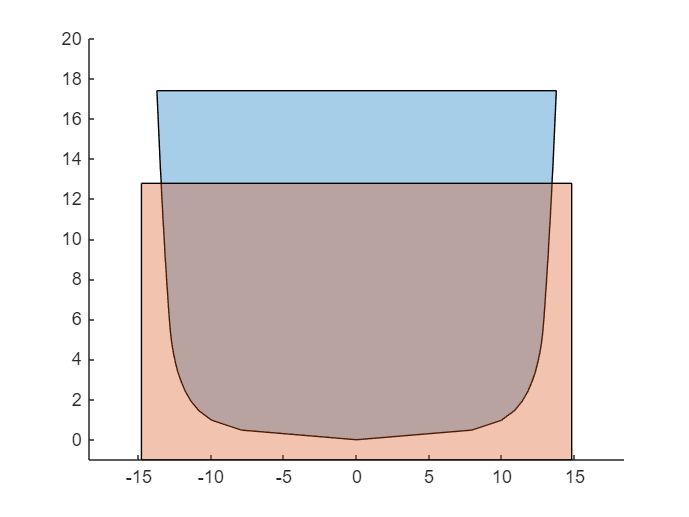

index = 17; % station (between 1 and # crosssections)
xPos = xUnique(index);
waterline_guess = 12.6+ zmin_all;
trim_guess = -0.01;
warning('off', 'all');
shape = internalShapes(index);
box = waterbox(waterline_guess + tan(trim_guess) * xPos, 1);
clf;
hold on;
ylim([-1 20]);
xlim([-zmax_all - 1 zmax_all + 1]);
plot(shape);
plot(box);
hold off;

% polyshape is weird asf and doesnt like when you try to transform it 3d.
% have to use patch and some weird Vertices bs
% hold on;
% view(3);
% for i = 1:numel(xUnique)
%     shape = internalShapes(i);
%     positions = shape.Vertices;
%     positions(:,3) = xUnique(i);
%     patch(positions(:,1),positions(:,2),positions(:,3));
%     axis vis3d
% end
% hold off;

## Finding the necessary load for a desired Freeboard

freeboard = 6; % (in)
draft_ideal = zmax_all - freeboard;
weightInitial = 400;
netforcefromweight = @(weight) trapz(xInterp,selfWeightInterp) ...
    + trapz(xUnique,buoyantdist([draft_ideal,0])) - weight;
objective = @(weight) (netforcefromweight(weight))^2 ; % squaring turns 0 into a local min
[weightIdeal, resultant] = fminsearch(objective,weightInitial,optimset('Display', 'off'));
disp("weight necessary for desired freeboard (lbf):  " + weightIdeal/LIVE_FACTOR);

weight necessary for desired freeboard (lbf):  740.2445


## Lol what if the whole canoe was filled with water and we had to put it on stands?

- Question from Paddling Team

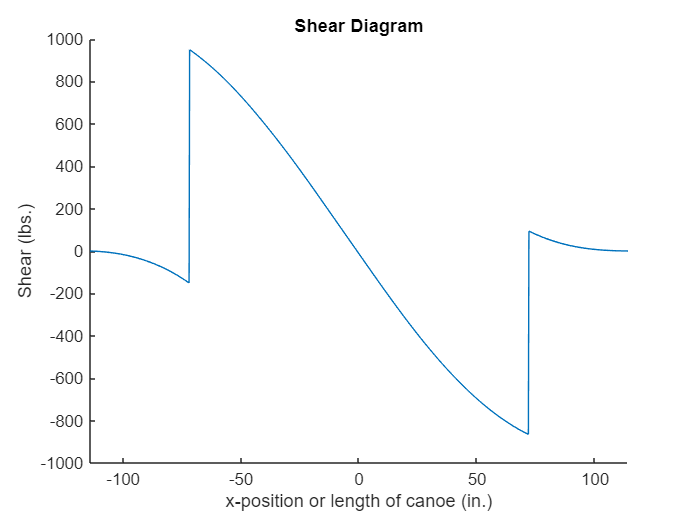

standSeperation = 144;
internalAreas = area(internalShapes);
internalAreasInterp = interp1(xUnique, internalAreas, xInterp, 'linear');
internalAreasInterp = internalAreasInterp .* 62.4/1728; % density of water
standpos = standSeperation/2;

moment = momentabout(-standpos,internalAreasInterp,xInterp);
netforce = abs(trapz(xInterp,internalAreasInterp));
reactions = [-standpos standpos; abs(netforce - moment/standSeperation) abs(moment/standSeperation) ];

[V, M] = shearmoment(xInterp,-internalAreasInterp,reactions);
close all

hold on;

plot(xInterp,V);
xlim([xInterp(1) xInterp(end)]);
title('Shear Diagram');
xlabel('x-position or length of canoe (in.)');
ylabel('Shear (lbs.)');

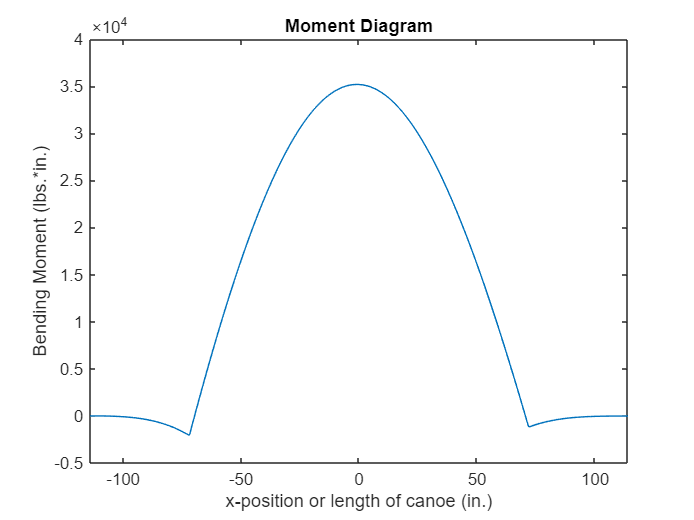


figure;

plot(xInterp,M);
xlim([xInterp(1) xInterp(end)]);
title('Moment Diagram');
xlabel('x-position or length of canoe (in.)');
ylabel('Bending Moment (lbs.*in.)');
hold off;


disp("Max bending: (lb*in) " + max(abs(M)));

Max bending: (lb*in) 35176.2987


## Moment Shear Debug

% x = [-3 -2 -1 -.01 .01 1 2 3];
% load = 100;
% dist = load/(max(x)-min(x));
% loadDist = zeros(numel(x),1);
% loadDist(:) = dist;
caseName = "SelfWeight";
disp(caseName);

SelfWeight


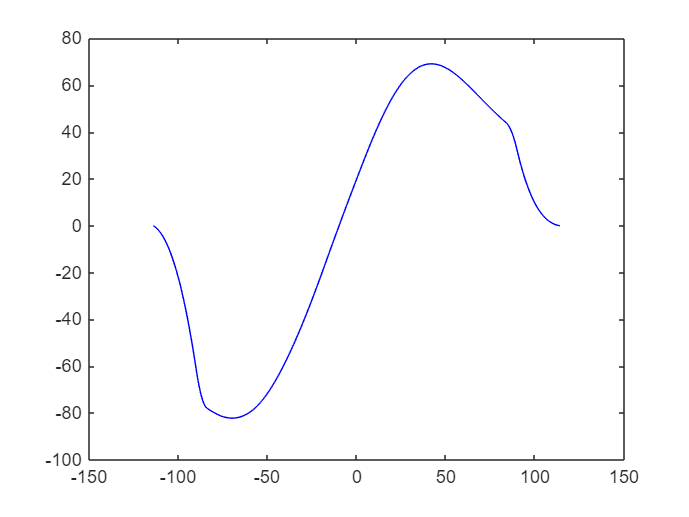

x = xInterp;
v = LoadCases.(caseName).ShearDistribution;
m = LoadCases.(caseName).MomentDistribution;

close all;
plot(x,v,'Color','b');

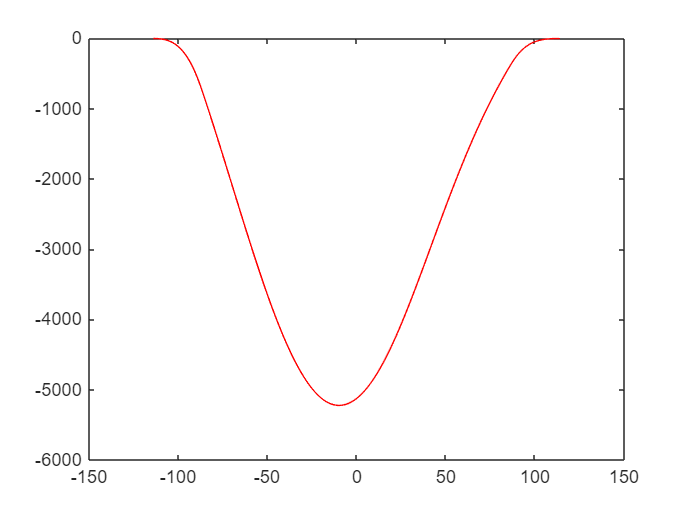

figure;
plot(x,m,'Color','r');

B = [-1 0 1 0 0; 0 -1 1 0 0; 0 0 -1 0 1; 0 0 -1 1 0; 0 0 0 -1 1];
C = [100 0 0 0 0; 0 150 0 0 0; 0 0 200 0 0; 0 0 0 150 0;  0 0 0 0 100];

K = B' * C * B;
disp(K);

   100     0  -100     0     0
     0   150  -150     0     0
  -100  -150   600  -150  -200
     0     0  -150   250  -100
     0     0  -200  -100   300

